clear; clc; close all;

%% -------------------- User Inputs ---------------------------------------
Te_C = 5;         % Evaporator saturation temperature [°C]
Tc_C = 40;        % Condenser saturation temperature [°C]
Qdot_cool = 2000; % Target cooling capacity [W] (e.g., 2 kW)

% Ideal-gas-ish vapor approximation in compressor (superheat leg):
k    = 1.10;                   % k ≈ cp/cv for R134a vapor
cp   = 0.90e3;                 % cp ≈ 0.90 kJ/kg-K -> 900 J/kg-K
Rgas = 81.5;                   % R ≈ 0.0815 kJ/kg-K -> 81.5 J/kg-K

%% -------------------- Sat states 1 and 3 (tables) -----------------------
% Minimal saturation table for R-134a (approximate!)
% T [°C], Psat [bar], h_f [kJ/kg], h_g [kJ/kg], s_f [kJ/kg-K], s_g [kJ/kg-K]
sat = [ ...
   -20   1.92   180   402   0.94   1.76;
   -10   2.63   190   401   0.97   1.76;
     0   3.92   200   398   1.01   1.76;
    10   5.70   210   397   1.05   1.77;
    20   7.60   222   395   1.09   1.77;
    30   9.80   235   393   1.13   1.78;
    40  12.20   249   392   1.17   1.79;
    50  15.20   265   392   1.22   1.81];
% (Numbers are rounded/illustrative; replace with real tables as needed.)

P1_bar = interp1(sat(:,1), sat(:,2), Te_C, 'linear','extrap');
P3_bar = interp1(sat(:,1), sat(:,2), Tc_C, 'linear','extrap');

h1 = interp1(sat(:,1), sat(:,4), Te_C);  % sat vapor enthalpy [kJ/kg]
s1 = interp1(sat(:,1), sat(:,6), Te_C);  % sat vapor entropy [kJ/kg-K]
h3 = interp1(sat(:,1), sat(:,3), Tc_C);  % sat liquid enthalpy [kJ/kg]
s3 = interp1(sat(:,1), sat(:,5), Tc_C);  % sat liquid entropy [kJ/kg-K]

T1 = Te_C + 273.15;            % K
P1 = P1_bar * 1e5;             % Pa (bar -> 1e5 Pa)
P2 = P3_bar * 1e5;             % Pa

%% -------------------- 1->2: Idealized isentropic compression -----------
% Use ideal-gas relations on the vapor leg to estimate T2, then h2.
T2 = T1 * (P2/P1)^((k-1)/k);          % isentropic ideal-gas
h2 = h1 + (cp/1000) * (T2 - T1);      % kJ/kg (cp in J/kg-K)

% (If you have real tables: solve s2=s1 at P2 for h2 and T2.)

%% -------------------- 2->3: Condensation to sat liquid ------------------
% Assume complete condensation to saturated liquid at Tc:
h3 = h3;  % already from table

%% -------------------- 3->4: Throttle (isenthalpic) ----------------------
h4 = h3;  % Joule–Thomson expansion (Δh ≈ 0)

%% -------------------- 4->1: Evaporation back to sat vapor ---------------
% Refrigeration effect per kg:
q_in = h1 - h4;      % kJ/kg
% Compressor specific work:
w_in = h2 - h1;      % kJ/kg
COP  = q_in / w_in;

% Mass flow for required cooling load:
mdot = Qdot_cool / (q_in*1000);   % kg/s

fprintf('--- R134a Cycle (approx) ---\n');

--- R134a Cycle (approx) ---


fprintf('Te = %.1f°C, Tc = %.1f°C\n', Te_C, Tc_C);

Te = 5.0°C, Tc = 40.0°C


fprintf('P_evap = %.2f bar, P_cond = %.2f bar\n', P1_bar, P3_bar);

P_evap = 4.81 bar, P_cond = 12.20 bar


fprintf('h1=%.1f, h2=%.1f, h3=%.1f, h4=%.1f  [kJ/kg]\n', h1,h2,h3,h4);

h1=397.5, h2=419.6, h3=249.0, h4=249.0  [kJ/kg]


fprintf('q_in=%.1f kJ/kg, w_in=%.1f kJ/kg, COP=%.2f\n', q_in, w_in, COP);

q_in=148.5 kJ/kg, w_in=22.1 kJ/kg, COP=6.72


fprintf('Mass flow for %.1f kW cooling: mdot = %.3f kg/s\n', Qdot_cool/1000, mdot);

Mass flow for 2.0 kW cooling: mdot = 0.013 kg/s


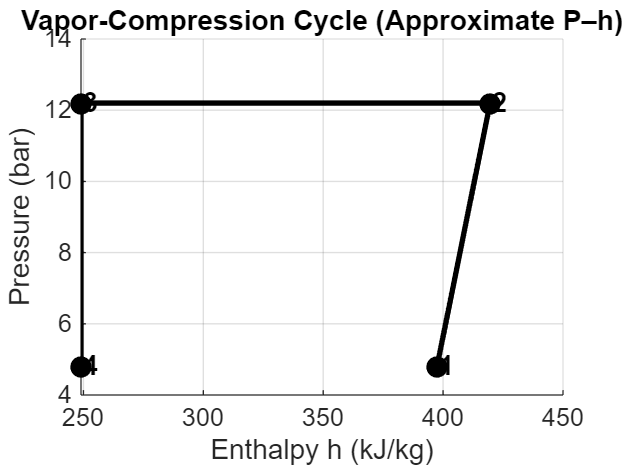


%% -------------------- Plots ---------------------------------------------
% "P-h" style (using just the four state points and straight lines)
Pbar = [P1_bar, P3_bar, P3_bar, P1_bar];      % bar
h    = [h1,     h2,     h3,     h4     ];     % kJ/kg
labels= {'1','2','3','4'};

figure('Color','w'); hold on; grid on;
plot(h, Pbar, 'o-k','LineWidth',2,'MarkerFaceColor','k');
for i=1:4
    text(h(i)+0.8, Pbar(i), labels{i}, 'FontWeight','bold');
end
xlabel('Enthalpy h (kJ/kg)');
ylabel('Pressure (bar)');
title('Vapor-Compression Cycle (Approximate P–h)');

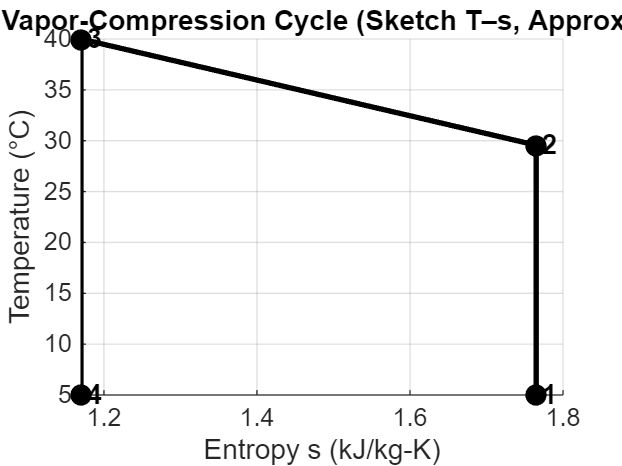


% "T-s" style (very approximate: use s1 for 1->2, and s3 for 3->4)
% With our coarse model, we’ll draw vertical-ish lines for isentropic/throttle.
s  = [s1, s1, s3, s3];      % kJ/kg-K (placeholders for the sketch)
T  = [T1, T2, Tc_C+273.15, Te_C+273.15];  % K
figure('Color','w'); hold on; grid on;
plot(s, T-273.15, 'o-k','LineWidth',2,'MarkerFaceColor','k');
for i=1:4
    text(s(i)+0.008, T(i)-273.15, labels{i}, 'FontWeight','bold');
end
xlabel('Entropy s (kJ/kg-K)');
ylabel('Temperature (°C)');
title('Vapor-Compression Cycle (Sketch T–s, Approx.)');